# Polynomial Least Regression Method

*MohammadSina GhanbariPakdehi, Chemical and Petroleum Engineering Department, Fall 2021*

Polynomial Least Regression Method, or Polynomial Regression, is a statistical approach used to model relationships between variables by fitting a polynomial curve to data points. Unlike linear regression, this method accommodates nonlinear patterns. It involves adjusting polynomial coefficients to minimize the squared differences between observed data and curve points. The polynomial's degree controls curve complexity, with higher degrees capturing intricate patterns but risking overfitting. Widely applied in diverse fields, Polynomial Regression unveils insights in nonlinear data trends for better predictions, demanding careful degree selection to balance model complexity and generalization. The general form of regression polynomial is $y=a_0 +a_1 x+a_2 x^2 +\ldotp \ldotp \ldotp +a_m x^m$. m stands for the maximum order of polynomial and its equal to the number of x data minus 1.

### Part1: Input data

clear, clc
x = [0, 20, 40, 60, 80, 100, 120, 140];
y = [13.4, 24, 30, 40, 48, 52, 49, 44];
n = length(x)-1;

degree = 3;  % Choose the desired degree of the polynomial

### Part2: Calculation process

In this part, a system of linear equations for finding the coefficients should be created. Its general form is:


$$\left\lbrack \begin{array}{ccccc}
n & \sum_i \;x_i  & \sum_i x_i^2 \; & \cdots  & \sum_i \;x_i^m \\
\sum_i \;x_i  & \sum_i \;x_i^2  & \sum_i \;x_i^3  & \cdots  & \sum_i \;x_i^{m+1} \\
\vdots  & \ddots  & \ddots  & \ddots  & \vdots \\
\sum_i \;x_i^m  & \sum_i \;x_i^{m+1}  & \sum_i \;x_i^{m+2}  & \cdots  & \sum_i \;x_i^{2m} 
\end{array}\right\rbrack \times \left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
\vdots \\
a_m 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\sum_i \;y_i \\
\sum_i x_i y_i \;\\
\vdots \\
\sum_i x_i^m y_i \;
\end{array}\right\rbrack$$


Coeff = zeros(degree + 1, degree + 1);
for i = 1:degree + 1
    for j = 1:degree + 1
        Coeff(i, j) = sum(x.^(i + j - 2));
    end
end

Ans = zeros(degree + 1, 1);
for i = 1:degree + 1
    Ans(i) = sum((x.^(i - 1)).*y);
end

Final = Coeff \ Ans;

### Part3: Visualization

Visualization is one of the fast methods to see how much the linearization is accurate. Note that visualization just shows the quality of accuracy not its value! 

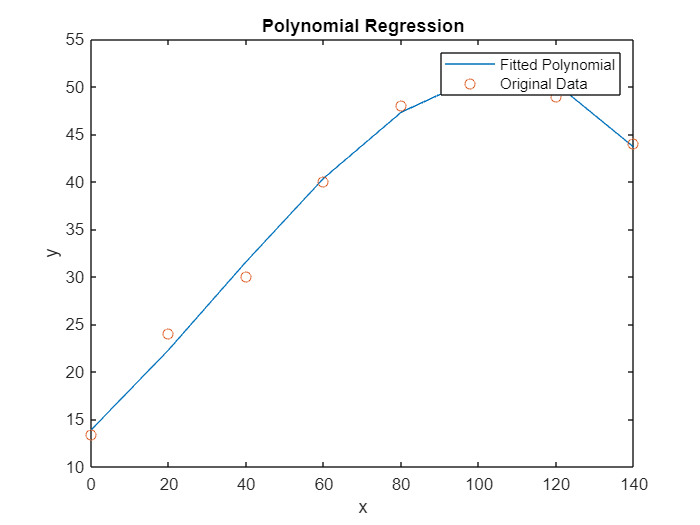

reg = polyval(flip(Final), x);
plot(x, reg);
hold on
plot(x, y, 'o');
xlabel('x');
ylabel('y');
title('Polynomial Regression');
legend('Fitted Polynomial', 'Original Data');

### Part4: Measurement of the linearization accuracy

Using Coefficient of determination ($r^2$), the accuracy of linearization can be measured easily. First, the Residual sum of squares should be calculated using the formula below:


$$S_r =\sum_{i=1}^n {\left(y_i -a_0 -a_1 x_i -a_2 x_i^2 -\ldotp \ldotp \ldotp -a_m x_i^m \right)}^2$$


Then, First, the mean deviation squares should be calculated by the following equation:


$$S_t =\sum_{i=1}^n {\left(y_i -\bar{y} \right)}^2$$



$$r^2 =\frac{\left(S_t -S_r \right)}{S_t }$$


y_new = ones(1,length(y));
for i= 1:length(y_new)
    y_new(i) = polyval(flip(Final), x(i));
end
Sr = sum((y - y_new).*(y - y_new));
St = sum((y- mean(y)).*(y- mean(y)));
r2 = (St - Sr)/St;
disp('The Coefficient of determination is: '), disp(r2)

The Coefficient of determination is: 
    0.9933

